Representa cómo varía la distorsión obtenida, vDist, en función de la iteración.

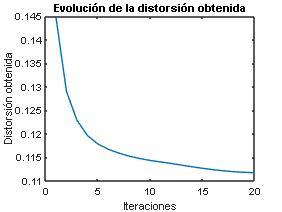

[VQ,vDist, no_asig]=Kmeans(traindata,6,[],1e-3,1);
plot(vDist)
xlabel('Iteraciones');
ylabel('Distorsión obtenida');
title('Evolución de la distorsión obtenida');

Ejecuta el algoritmo Kmeans 20 veces. Guarda el tiempo de ejecución y la distorsión de la ultima iteración de cada ejecución. Represéntalos gráficamente.


iteracionNum = 20;

% Creamos los arrays para guardar la data:
executionTimes = zeros(1, iteracionNum);
distortions = zeros(1, iteracionNum);

for i = 1:iteracionNum
    % Ponemos el timer
    tic;
    [VQ,vDist, no_asig]=Kmeans(traindata,6,[],1e-3,1);
    
    
    distorX=vDist(end);
    executionTime = toc;
    
    executionTimes(i) = executionTime;
    distortions(i)=distorX;
    
end

% Representamos:
figure(1);
plot(1:iteracionNum, executionTimes, '-o');
xlabel('Ronda');
ylabel('Tiempo de ejecución');
title('Execution');
grid on;

figure(2);

plot(1:iteracionNum, distortions, '-o');
xlabel('Ronda');
ylabel('Distorsiones');
title('Distorsiones de cada ultima iteración');
grid on;

Forma la matriz training que contenga pares, no solapados, de muestras consecutivas por filas. Cada fila será un vector de datos de dimensión 2.

audioFilePath = 'C:\Users\34698\Downloads\datos_funciones\datos\tvg_training_20s.wav'; 

audioData = audioread(audioFilePath);

numSamples = length(audioData);

windowSize = 2;

numPairs = floor(numSamples / windowSize);

training = zeros(numPairs, windowSize);

for i = 1:numPairs
    startIndex = (i - 1) * windowSize + 1;
    endIndex = i * windowSize;
    training(i, :) = audioData(startIndex:endIndex);
end

Sobre una misma gráfica representar los datos de partida y los centroides del VQ resultante.

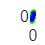

[VQ,vDist, no_asig]=Kmeans(training,6,[],1e-2,1);

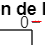


figure;

plot(training,'r-');
hold on;

plot(VQ,'b-');
hold off;

title('Comparación de las distorsiones');
legend('Datos de partida','Centroides resultantes')

Representa cómo varía la distorsión obtenida en función de la iteración. 

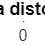

plot(vDist)
xlabel('Iteraciones'); % Label for the x-axis
ylabel('Distorsión obtenida'); % Label for the y-axis

% Add a title to the plot
title('Evolución de la distorsión obtenida');